clc; clear all; close all;
A=[0 1 2; -1 -2.3 4.5;0 -1 -1.4]; 
B=[2 3;
    0 1;
    -1 -2]; 
C=[1 0 0;0 0 0; 0 0 0];


D=0;

% Parámetros del MPC
Ts = 0.2;         % Tiempo de muestreo
N = 50;            % Horizonte de predicción
Qy = diag([100;100;100])         % Penalización de la salida

Qy =    100     0     0
     0   100     0
     0     0   100


R = diag([0.1;0.01])      % Penalización del control

R =     0.1000         0
         0    0.0100


yref = [1;0;0]        % Referencia deseada

yref =      1
     0
     0


x0 = [0;0;1];      % Estado inicial
Qf = 100*Qy;  



% Llamada a la función MPC
[X, U] = mpc_controller(A, B, C, D, Ts, N, Qy, R, yref, x0, Qf);

Qbig =    100     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0   100     0     0     0     0     0     0     0     0     0     0     0

Qbig = 1.0e+04 *

    0.0100         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

q =   -100
     0
     0
  -100
     0
     0
  -100
     0
     0
  -100


Umax =      0
    10


Umin =      0
   -10


Aineq =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0    -1     0     0     0     0     0     0     0     0     0     0     0     0     

bineq =     10
    10
     2
     2
    10
    10
     2
     2
    10
    10



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


z =     0.9997
    0.5302
    0.3054
    1.0000
    0.3281
    0.2711
    1.0000
    0.1928
    0.2488
    1.0000


X

X =     0.9997    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    0.5302    0.3281    0.1928    0.1027    0.0429    0.0035   -0.0222   -0.0389   -0.0495   -0.0561   -0.0601   -0.0624   -0.0635   -0.0641   -0.0641   -0.0640   -0.0637   -0.0633   -0.0630   -0.0626   -0.0623   -0.0619   -0.0617   -0.0614   -0.0612   -0.0610   -0.0608   -0.0607   -0.0605   -0.0604   -0.0603   -0.0602   -0.0601   -0.0600   -0.0600   -0.0599   -0.0598   -0.0597   -0.0596   -0.0595   -0.0595   -0.0593   -0.0592   -0.0591   -0.0589   -0.0587   -0.0585   -0.0582   -0.0579   -0

U

U =     0.0613   -0.0312   -0.0258   -0.0223   -0.0200   -0.0185   -0.0175   -0.0169   -0.0165   -0.0163   -0.0162   -0.0162   -0.0161   -0.0161   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0161   -0.0161   -0.0160   -0.0160   -0.0159   -0.0158   -0.0157   -0.0155   -0.0154   -0.0152   -0.0149   -0.0147   -0.0144   -0.0140   -0.0136   -0.0131   -0.0126   -0.0120   -0.0113   -0.0106   -0.0099   -0.0092   -0.0086   -0.0082
    1.0773   -0.3095   -0.2399   -0.1934   -0.1629   -0.1429   -0.1299   -0.1217   -0.1166   -0.1135   -0.1117   -0.1108   -0.1104   -0.1103   -0.1104   -0.1107   -0.1110   -0.1113   -0.1116   -0.1118   -0.1121   -0.1123   -0.1125   -0.1127   -0.1129   -0.1131   -0.1132   -0.1134   -0.1135   -0.1137   -0.1138   -0.1140   -0.1141   -0.1143   -0.1145   -0.1147   -0.1149   -0.1152   -0.1155   -0.1159   -0.1163   -0.1167   -0.1173   -0.1178   -0.1185   -0.1192   -0.1200   -0.1207   -0.1215   -0

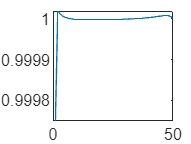

figure
plot(X(1,:));  

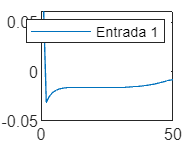


figure
plot(U(1,:))
legend('Entrada 1')

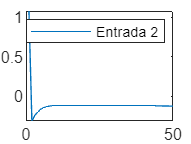


figure
plot(U(2,:));  
legend('Entrada 2')

function [X, U] = mpc_controller(A, B, C, D, Ts, N, Qy, R, yrefk, x0, Qf)
    sysc = ss(A, B, C, D);
    sysd = c2d(sysc, Ts, 'zoh');
    Ad = sysd.A;
    Bd = sysd.B;
    
    nx = size(A, 1); 
    nu = size(B, 2);
    ny = size(C, 1);

    % Función de costo
    Qbig = blkdiag(kron(eye(N), C' * Qy * C), kron(eye(N), R))

    Qbig(nx*(N-1)+(1:nx),nx*(N-1)+(1:nx)) = C'*Qy*C+C'*Qf*C
    
    % Asegurar que yrefk tenga dimensiones correctas
    if size(yrefk, 2) ~= 1
        error('yrefk debe ser un vector columna de tamaño (ny, 1)')
    end
    q = -[repmat(C' * Qy * yrefk, N, 1); zeros(N*nu, 1)];
    q(nx*(N-1)+(1:nx),1)=-C'*Qy*yrefk-C'*Qf*yrefk
    
    % Restricciones de igualdad 

    Aeq = zeros(N * nx, N * (nx + nu));
    beq = zeros(N * nx, 1);

    for k = 1:N
        Aeq((k-1)*nx+1:k*nx, (k-1)*nx+1:k*nx) = -eye(nx);
        if k == 1
            Aeq(1:nx, 1:nx) = -eye(nx);
            Aeq(1:nx, nx*N+1:nx*N+nu) = Bd;
            beq(1:nx) = -Ad * x0;
        else
            Aeq((k-1)*nx+1:k*nx, (k-2)*nx+1:(k-1)*nx) = Ad;
            Aeq((k-1)*nx+1:k*nx, nx*N+(k-1)*nu+1:nx*N+k*nu) = Bd;
        end
    end

    Aineq = [];
    bineq = [];

    %------------------------
    % Restricciones de control y estados
    Umax = [0;10]
    Umin = [0;-10]

    Xmax = [10;2;0];
    Xmin = [-10;-2;0];

    %--------------------------

    [Aineq, bineq] = restricciones(nx, nu, N, Xmin, Xmax, Umin, Umax)
    
    % Resolver el problema de optimización cuadrática
    z = quadprog(Qbig, q, Aineq, bineq, Aeq, beq)

    X = reshape(z(1:nx*N), nx, N);
    U = reshape(z(nx*N+1:end), nu, N);
end
function [Aineq, bineq] = restricciones(nx, nu, N, Xmin, Xmax, Umin, Umax, sat_start, sat_end)

    if nargin < 8 || isempty(sat_start)
        sat_start = 1;
    end
    if nargin < 9 || isempty(sat_end)
        sat_end = N;
    end

    nvar = nx * N + nu * N;
    
    Aineq = [];
    bineq = [];
    
    
    for t = 1:N
        
        if t < sat_start || t > sat_end
            continue;
        end
        for i = 1:nx
            idx = (t-1)*nx + i; 

            if ~isempty(Xmax)
                if ~( Xmax(i)==0 && ~isempty(Xmin) && Xmin(i)==0 )
                    row = zeros(1, nvar);
                    row(idx) = 1;
                    Aineq = [Aineq; row];
                    bineq = [bineq; Xmax(i)];
                end
            end

            if ~isempty(Xmin)
                if ~( Xmin(i)==0 && ~isempty(Xmax) && Xmax(i)==0 )
                    row = zeros(1, nvar);
                    row(idx) = -1;
                    Aineq = [Aineq; row];
                    bineq = [bineq; -Xmin(i)];
                end
            end
        end
    end
    
    %% Restricciones para las entradas
    for t = 1:N
        % Aplicar restricciones solo si t está dentro del tramo definido:
        if t < sat_start || t > sat_end
            continue;
        end
        for j = 1:nu
            idx = nx * N + (t-1)*nu + j; 
            % Restricción superior: u_j(t) <= Umax(j)
            if ~isempty(Umax)
                if ~( Umax(j)==0 && ~isempty(Umin) && Umin(j)==0 )
                    row = zeros(1, nvar);
                    row(idx) = 1;
                    Aineq = [Aineq; row];
                    bineq = [bineq; Umax(j)];
                end
            end
            
            % Restricción inferior: u_j(t) >= Umin(j)
            if ~isempty(Umin)
                if ~( Umin(j)==0 && ~isempty(Umax) && Umax(j)==0 )
                    row = zeros(1, nvar);
                    row(idx) = -1;
                    Aineq = [Aineq; row];
                    bineq = [bineq; -Umin(j)];
                end
            end
        end
    end
end


